% For computation define as function of 1 vector variable
F.f = @(x) (x(1) - 3*x(2)).^2 + x(1).^4;
F.df = @(x) [2*(x(1) - 3*x(2)) + 4*x(1).^3; -6*(x(1) - 3*x(2))];
F.d2f = @(x) [2 + 12*x(1).^2, -6; -6, 18];

% Starting point
x0 = [10; 10]; 

% Parameters
maxIter = 200; 
tol = 1e-10; % Stopping tolerance on relative step length between iterations

% Line search parameters
alpha0 = 1;

% Strong Wolfe LS
lsOpts_LS.c1 = 1e-4;
lsOpts_LS.c2 = 0.9; % 0.1 Good for Newton, 0.9 - good for steepest descent, 0.5 compromise.
lsFunS = @(x_k, p_k, alpha0) lineSearch(F, x_k, p_k, alpha0, lsOpts_LS);
lsFun = lsFunS;


%What I need to do: 1) Initialize H_0 to the eye of the @(x)
%eye(length(x0)); // 2) Set p_0 and x_1 with linesearch alpha

% Parameters
% Stopping condition {'step', 'grad'}
stopType = 'grad';

% Extract inverse Hessian approximation handler
extractH = 1;

% Initialization
nIter = 0;
x_k = x0;
info.xs = x0;
info.alphas = alpha0;
stopCond = false; 




H_k = @(y) eye(length(y));
    % Store H matrix in columns
info.H = [];


H_k = H_k(x_k)

H_k =      1     0
     0     1



% Loop until convergence or maximum number of iterations
while (~stopCond && nIter <= maxIter)
    
  % Increment iterations
    nIter = nIter + 1;

    % Compute descent direction


        %======================== Descent direction ==========================================
    p_k = -H_k*F.df(x_k);

        %==================================================================================

    
    % Call line search given by handle ls for computing step length
    alpha_k = lsFun(x_k, p_k, alpha0);
    
    % Update x_k and f_k
    x_k_1 = x_k
    x_k = x_k + alpha_k*p_k

    
          
        %======================== s_k and y_k  ==========================================
        
     s_k = x_k - x_k_1;
     y_k = F.df(x_k) - F.df(x_k_1);
        %==================================================================================
        
     if nIter == 1
          % Update initial guess H_0. Note that initial p_0 = -F.df(x_0) and x_1 = x_0 + alpha * p_0.
        disp(['Rescaling H0 with ' num2str((s_k'*y_k)/(y_k'*y_k)) ])
        H_k = @(x) (s_k'*y_k)/(y_k'*y_k) * x;
        H_k = H_k(eye(length(x_k_1)));

        info.H{length(info.H)+1} = H_k;
     end
        
        
        %======================== Hessian Approximation Update ==========================================
        ro_k = 1 / (y_k'*s_k);
        H_k = (eye(length(x_k)) - ro_k*s_k*y_k')*H_k*(eye(length(x_k)) - ro_k*y_k*s_k') + ro_k*s_k*s_k'
        %==================================================================================
        
      if extractH
            % Extraction of H_k as handler
         info.H{length(info.H)+1} = H_k;
      end
    
    

    % Store iteration info
    info.xs = [info.xs x_k];
    info.alphas = [info.alphas alpha_k];
    
    switch stopType
      case 'step' 
        % Compute relative step length
        normStep = norm(x_k - x_k_1)/norm(x_k_1);
        stopCond = (normStep < tol);
      case 'grad'
        stopCond = (norm(F.df(x_k), 'inf') < tol*(1 + abs(F.f(x_k))));
    end
end

x_k_1 =     10
    10


x_k =   -3.921875000000000
   9.578125000000000


Rescaling H0 with 0.0032602


H_k =    0.003265783318425   0.000157073081899
   0.000157073081899   0.003269709572085


x_k_1 =   -3.921875000000000
   9.578125000000000


x_k =   -3.048403139711297
   9.044875402327078


H_k =    0.006202987794746  -0.003297904446180
  -0.003297904446180   0.006393491996324


x_k_1 =   -3.048403139711297
   9.044875402327078


x_k =   -1.541290642511745
   7.487313362481840


H_k =    0.010473707782950  -0.009284482866942
  -0.009284482866942   0.014206017719082


x_k_1 =   -1.541290642511745
   7.487313362481840


x_k =    0.252721808660430
   5.122441019668624


H_k =    0.019587452816387  -0.021706802248751
  -0.021706802248751   0.031119712515349


x_k_1 =    0.252721808660430
   5.122441019668624


x_k =    2.556169570855062
   1.993185907755052


H_k =    0.013609434716632  -0.015351766874479
  -0.015351766874479   0.024885679521647


x_k_1 =    2.556169570855062
   1.993185907755052


x_k =    2.105531407503181
   2.361602592308209


H_k =    0.011684442180836  -0.007491054707324
  -0.007491054707324   0.013319342009510


x_k_1 =    2.105531407503181
   2.361602592308209


x_k =    2.019034690260383
   2.188058324456680


H_k =    0.017829987218859   0.008928354775146
   0.008928354775146   0.054467130958360


x_k_1 =    2.019034690260383
   2.188058324456680


x_k =    1.417465755494342
   0.659726906641063


H_k =    0.020953537012285   0.013278505221542
   0.013278505221542   0.056409874107210


x_k_1 =    1.417465755494342
   0.659726906641063


x_k =    1.183543126337528
   0.365905619051875


H_k =    0.040191314035130   0.024360255683370
   0.024360255683370   0.053897327580383


x_k_1 =    1.183543126337528
   0.365905619051875


x_k =    0.948748034421771
   0.241730931969647


H_k =    0.071882519521928   0.028381819362139
   0.028381819362139   0.049287107158776


x_k_1 =    0.948748034421771
   0.241730931969647


x_k =    0.733092063022904
   0.202553395400887


H_k =    0.115628071437583   0.033623067564305
   0.033623067564305   0.049747701729501


x_k_1 =    0.733092063022904
   0.202553395400887


x_k =    0.565760793120766
   0.180969095018348


H_k =    0.188265760963477   0.051362310026738
   0.051362310026738   0.053115519103183


x_k_1 =    0.565760793120766
   0.180969095018348


x_k =    0.441618682478038
   0.151926532210581


H_k =    0.320891287910284   0.096834853996598
   0.096834853996598   0.067133069548699


x_k_1 =    0.441618682478038
   0.151926532210581


x_k =    0.342897889383336
   0.119236673256292


H_k =    0.538743247071681   0.179210728598668
   0.179210728598668   0.097800577573764


x_k_1 =    0.342897889383336
   0.119236673256292


x_k =    0.264732549748017
   0.090180898418071


H_k =    0.891302327704358   0.307677402819200
   0.307677402819200   0.144592713263351


x_k_1 =    0.264732549748017
   0.090180898418071


x_k =    0.204868834261208
   0.068311710993389


H_k =    1.490382340382077   0.511832036833881
   0.511832036833881   0.213803924493654


x_k_1 =    0.204868834261208
   0.068311710993389


x_k = 2×1
   0.158728730884136
   0.052452509123814


H_k = 2×2
   2.504035858633544   0.842941321209651
   0.842941321209651   0.321665234800959


x_k_1 = 2×1
   0.158728730884136
   0.052452509123814


x_k = 2×1
   0.122739546220572
   0.040618013703005


H_k = 2×2
   4.182640901081157   1.388273221940875
   1.388273221940875   0.498801981005693


x_k_1 = 2×1
   0.122739546220572
   0.040618013703005


x_k = 2×1
   0.094868743851477
   0.031549111733466


H_k = 2×2
   6.983437437885810   2.310273020147092
   2.310273020147092   0.802276464052684


x_k_1 = 2×1
   0.094868743851477
   0.031549111733466


x_k = 2×1
   0.073382264213097
   0.024486335437137


H_k = 2×2
  11.694642615857548   3.881026205196284
   3.881026205196284   1.325873967714027


x_k_1 = 2×1
   0.073382264213097
   0.024486335437137


x_k = 2×1
   0.056752855853377
   0.018951932973629


H_k = 2×2
  19.575768604838082   6.521990832603484
   6.521990832603484   2.210819589223991


x_k_1 = 2×1
   0.056752855853377
   0.018951932973629


x_k = 2×1
   0.043872635743238
   0.014639600580456


H_k = 2×2
  32.728191035823876  10.924653871647340
  10.924653871647340   3.684574047125718


x_k_1 = 2×1
   0.043872635743238
   0.014639600580456


x_k = 2×1
   0.033919230887691
   0.011307703177549


H_k = 2×2
  54.748738845049310  18.274208116203294
  18.274208116203294   6.137531722801257


x_k_1 = 2×1
   0.033919230887691
   0.011307703177549


x_k = 2×1
   0.026227151925478
   0.008739422625649


H_k = 2×2
  91.628118880217457  30.558814933678175
  30.558814933678175  10.229540003463345


x_k_1 = 2×1
   0.026227151925478
   0.008739422625649


x_k = 2×1
   0.020276997108964
   0.006756809639043


H_k = 2×2
	1.0e+02 *

   1.532941007616360   0.510917144250612
   0.510917144250612   0.170663686812577


x_k_1 = 2×1
   0.020276997108964
   0.006756809639043


x_k = 2×1
   0.015675914649262
   0.005224649518174


H_k = 2×2
	1.0e+02 *

   2.564338405429229   0.854507808159244
   0.854507808159243   0.285124442909753


x_k_1 = 2×1
   0.015675914649262
   0.005224649518174


x_k = 2×1
   0.012119505407345
   0.004039958943378


H_k = 2×2
	1.0e+02 *

   4.290595503438723   1.429899707887666
   1.429899707887666   0.476912627533692


x_k_1 = 2×1
   0.012119505407345
   0.004039958943378


x_k = 2×1
   0.009369932126675
   0.003123549985255


H_k = 2×2
	1.0e+02 *

   7.178967244415555   2.392893252030520
   2.392893252030520   0.797978108046150


x_k_1 = 2×1
   0.009369932126675
   0.003123549985255


x_k = 2×1
   0.007243917640002
   0.002414759971412


H_k = 2×2
	1.0e+03 *

   1.201060206411129   0.400374682552271
   0.400374682552271   0.133503219647011


x_k_1 = 2×1
   0.007243917640002
   0.002414759971412


x_k = 2×1
   0.005600307579217
   0.001866786689944


H_k = 2×2
	1.0e+03 *

   2.009458920233891   0.669859767788565
   0.669859767788565   0.223337863001608


x_k_1 = 2×1
   0.005600307579217
   0.001866786689944


x_k = 2×1
   0.004329671565551
   0.001443205236314


H_k = 2×2
	1.0e+03 *

   3.362106285619905   1.120732471949581
   1.120732471949581   0.373625512418965


x_k_1 = 2×1
   0.004329671565551
   0.001443205236314


x_k = 2×1
   0.003347302339497
   0.001115751382272


H_k = 2×2
	1.0e+03 *

   5.625155194352867   1.875047081659845
   1.875047081659845   0.625052040311235


x_k_1 = 2×1
   0.003347302339497
   0.001115751382272


x_k = 2×1
   0.002587811526794
   0.000862598268002


H_k = 2×2
	1.0e+03 *

   9.411353033933885   3.137076359488633
   3.137076359488633   1.045716243645401


x_k_1 = 2×1
   0.002587811526794
   0.000862598268002


x_k = 2×1
   0.002000653159309
   0.000666884812131


H_k = 2×2
	1.0e+04 *

   1.574620222452675   0.524868292780173
   0.524868292780173   0.174958182310541


x_k_1 = 2×1
   0.002000653159309
   0.000666884812131


x_k = 2×1
   0.001546718440416
   0.000515574452303


H_k = 2×2
	1.0e+04 *

   2.634516197601847   0.878169827810495
   0.878169827810495   0.292726319513458


x_k_1 = 2×1
   0.001546718440416
   0.000515574452303


x_k = 2×1
   0.001195775566264
   0.000398592786282


H_k = 2×2
	1.0e+04 *

   4.407809801866653   1.469272760478458
   1.469272760478458   0.489762318609228


x_k_1 = 2×1
   0.001195775566264
   0.000398592786282


x_k = 2×1
	1.0e+-3 *

   0.924459785586549
   0.308153447269954


H_k = 2×2
	1.0e+04 *

   7.374713234532011   2.458244185678660
   2.458244185678660   0.819420665110675


x_k_1 = 2×1
	1.0e+-3 *

   0.924459785586549
   0.308153447269954


x_k = 2×1
	1.0e+-3 *

   0.714704887770078
   0.238234850980025


H_k = 2×2
	1.0e+05 *

   1.233868546210544   0.411290070787868
   0.411290070787868   0.137097254350117


x_k_1 = 2×1
	1.0e+-3 *

   0.714704887770078
   0.238234850980025


x_k = 2×1
	1.0e+-3 *

   0.552542032805017
   0.184180561518444


H_k = 2×2
	1.0e+05 *

   2.064392076273893   0.688130710192842
   0.688130710192842   0.229377288390809


x_k_1 = 2×1
	1.0e+-3 *

   0.552542032805017
   0.184180561518444


x_k = 2×1
	1.0e+-3 *

   0.427172895954739
   0.142390919400859


H_k = 2×2
	1.0e+05 *

   3.453941233699034   1.151313130092331
   1.151313130092332   0.383771217499059


x_k_1 = 2×1
	1.0e+-3 *

   0.427172895954739
   0.142390919400859


x_k = 2×1
	1.0e+-3 *

   0.330249478955970
   0.110083159167125


H_k = 2×2
	1.0e+05 *

   5.778805690143523   1.926267702327068
   1.926267702327068   0.642089326050328


x_k_1 = 2×1
	1.0e+-3 *

   0.330249478955970
   0.110083159167125


x_k = 2×1
	1.0e+-3 *

   0.255317531536685
   0.085105854823379


H_k = 2×2
	1.0e+05 *

   9.668551403424653   3.222849997659680
   3.222849997659679   1.074283554796177


x_k_1 = 2×1
	1.0e+-3 *

   0.255317531536685
   0.085105854823379


x_k = 2×1
	1.0e+-3 *

   0.197387233959835
   0.065795751708614


H_k = 2×2
	1.0e+06 *

   1.617649828593549   0.539216644348383
   0.539216644348383   0.179738930951115


x_k_1 = 2×1
	1.0e+-3 *

   0.197387233959835
   0.065795751708614


x_k = 2×1
	1.0e+-3 *

   0.152601031501466
   0.050867012260508


H_k = 2×2
	1.0e+06 *

   2.706497345111016   0.902165883424437
   0.902165883424437   0.300722032944322


% % 
% % % % Assign output values 
xMin = x_k;
fMin = F.f(x_k); 

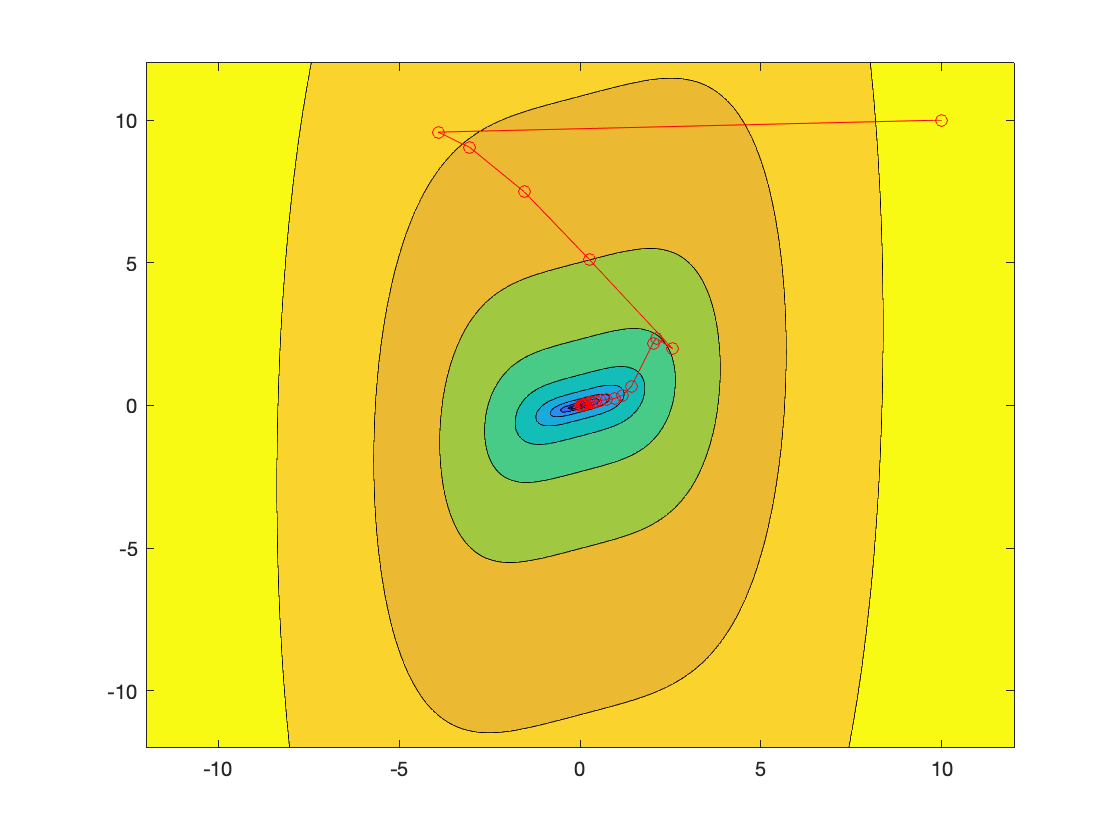

% Define grid for visualisation
n = 300;
x = linspace(-12,12,n+1); %rosenbrock
%x = linspace(-5, 10,n+1); %quartic2
F.V.f = @(x,y) (x - 3*y).^2 + x.^4;
y = x;
[X,Y] = meshgrid(x,y);
Z = log(max(F.V.f(X,Y), 1e-3));
% close by point subgrid
indT1 = floor(2/3*n)+(1:floor(n/3));

figure, contourf(X, Y, Z,10); hold on
plot(info.xs(1,:), info.xs(2,:), 'or-')
%title('Steepest descent method with backtracking line search, x_0 = [1.2;1.2]')
saveas(gcf,'Artworks/3aBFGS1.png')

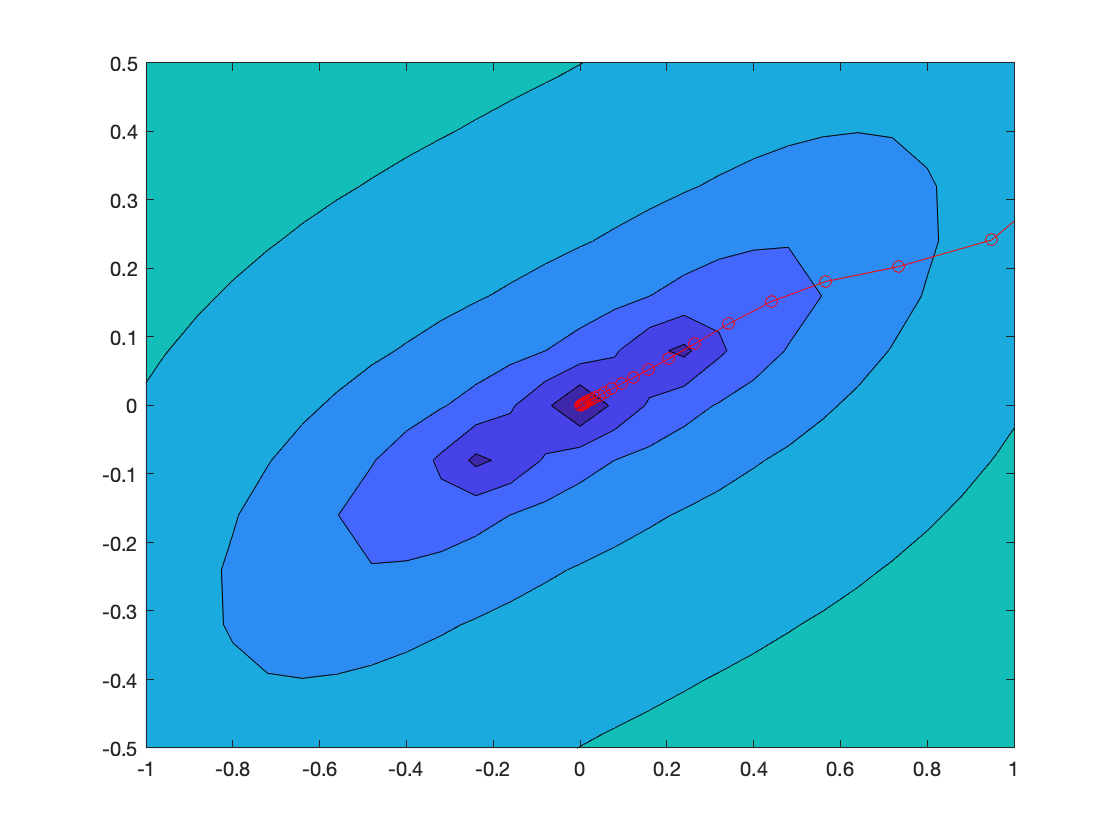

% Define grid for visualisation
n = 300;
x = linspace(-12,12,n+1); %rosenbrock
%x = linspace(-5, 10,n+1); %quartic2
F.V.f = @(x,y) (x - 3*y).^2 + x.^4;
y = x;
[X,Y] = meshgrid(x,y);
Z = log(max(F.V.f(X,Y), 1e-3));
% close by point subgrid
indT1 = floor(2/3*n)+(1:floor(n/3));

figure, contourf(X, Y, Z,10); hold on
plot(info.xs(1,:), info.xs(2,:), 'or-')
xlim([-1 1])
ylim([-0.5 0.5])
%title('Steepest descent method with backtracking line search, x_0 = [1.2;1.2]')
saveas(gcf,'Artworks/3aBFGS1-zoomed.png')

%Investigating the approximation 
ei = []


ei =

     []



for i = 1:length(info.H)-1
 ei(end+1)= norm(eye(length(x0)) - info.H{1,i}*F.d2f(info.xs(:,i)))
end

ei =    2.918853662682553


ei =    2.918853662682553   0.942241602802968


ei =    2.918853662682553   0.942241602802968   0.981441802308784


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753   0.318372696682658


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753   0.318372696682658   1.314785769796238


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753   0.318372696682658   1.314785769796238   1.791647065166399


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753   0.318372696682658   1.314785769796238   1.791647065166399   1.042198921912193


ei =    2.918853662682553   0.942241602802968   0.981441802308784   0.961236977490761   1.032016642738447   1.459676099434055   0.936302493744504   0.213280082459233   0.544908014120633   0.482431139574986   0.342095883383351   0.333761405819248   0.428320881542956   0.421345815642427   0.316305973516178   0.397986113430839   0.459069927455262   0.369162396500274   0.368631250634596   0.527540166184364   0.523437301670213   0.342431989605223   0.458904051848997   0.602512981380766   0.471016208646283   0.374816324894905   0.685693894736718   0.732436588881268   0.415266799832465   0.548825576873083   0.870370782487721   0.698417630434865   0.356451192788607   0.936987238384924   1.119483697333214   0.605962257385354   0.662553616579018   1.324114411762557   1.155600307223753   0.318372696682658   1.314785769796238   1.791647065166399   1.042198921912193   0.775574017958402


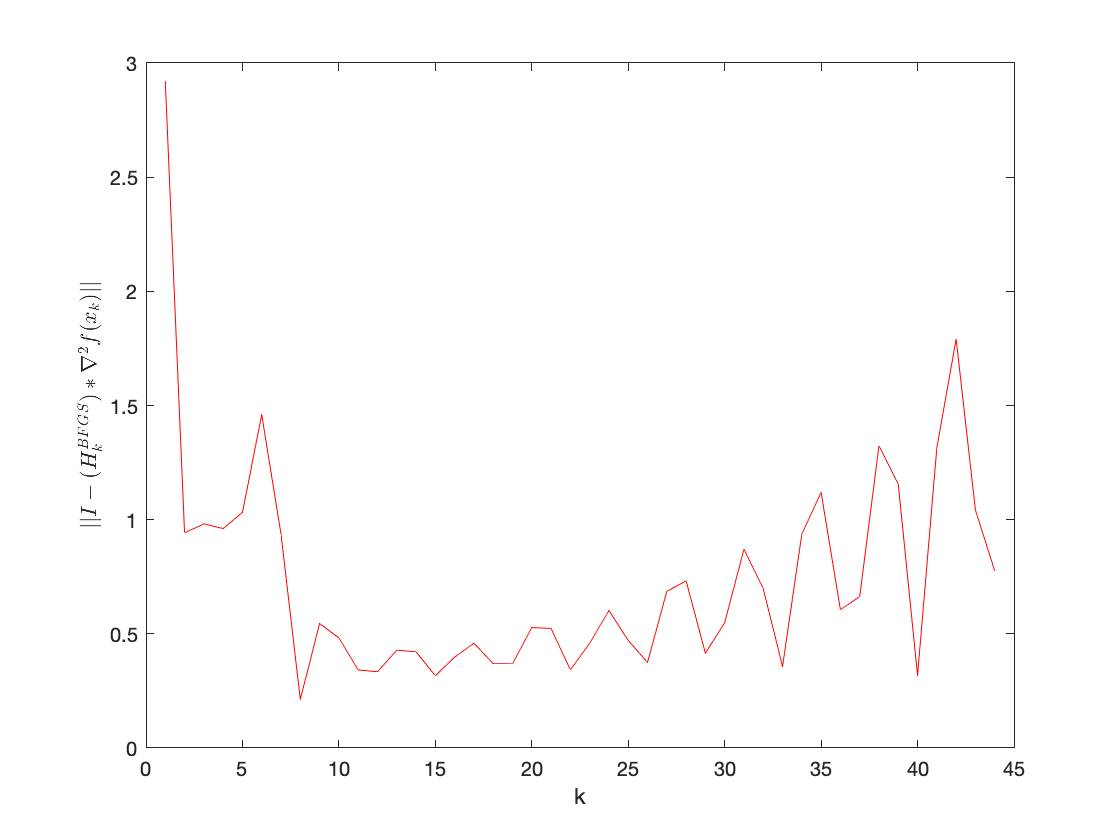

figure, plot(ei, 'r-')
xlabel('k')
ylabel('$|| I -(H_{k}^{BFGS}) * \nabla^{2}f(x_{k})||$', 'Interpreter',"latex")
saveas(gcf, 'Artworks/3ei-bfgs.png' )


eii = []


eii =

     []



for i = 1:length(info.H)-1
eii(end+1)= norm(inv(info.H{1,i}) - F.d2f(info.xs(:,i)))
end

eii =      8.953002972794585e+02


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049


eii = 	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130


eii = 1×9
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831


eii = 1×10
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873


eii = 1×11
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571


eii = 1×12
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525


eii = 1×13
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078


eii = 1×14
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940


eii = 1×15
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631


eii = 1×16
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964


eii = 1×17
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656


eii = 1×18
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209


eii = 1×19
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478


eii = 1×20
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772


eii = 1×21
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955


eii = 1×22
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596


eii = 1×23
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063


eii = 1×24
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774


eii = 1×25
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806


eii = 1×26
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642


eii = 1×27
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681


eii = 1×28
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919


eii = 1×29
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089


eii = 1×30
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×31
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×32
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×33
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×34
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×35
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×36
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×37
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×38
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×39
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×40
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×41
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×42
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×43
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


eii = 1×44
	1.0e+02 *

   8.953002972794586   2.889991460405172   2.815756168922286   3.290375747591897   3.430150269388174   2.944768911562208   1.709687347767049   0.118243461092130   0.317746231068831   0.217858549622873   0.113597465183571   0.073417916596525   0.077238177836078   0.088762534012940   0.091307356077631   0.092003317792964   0.094222433796656   0.093835891166209   0.092084777707478   0.092088807790772   0.092912332633955   0.093070622710596   0.093026718338063   0.093187665229774   0.093233876011806   0.093137717519642   0.093127106285681   0.093181834881919   0.093193526680089   0.093185777791183


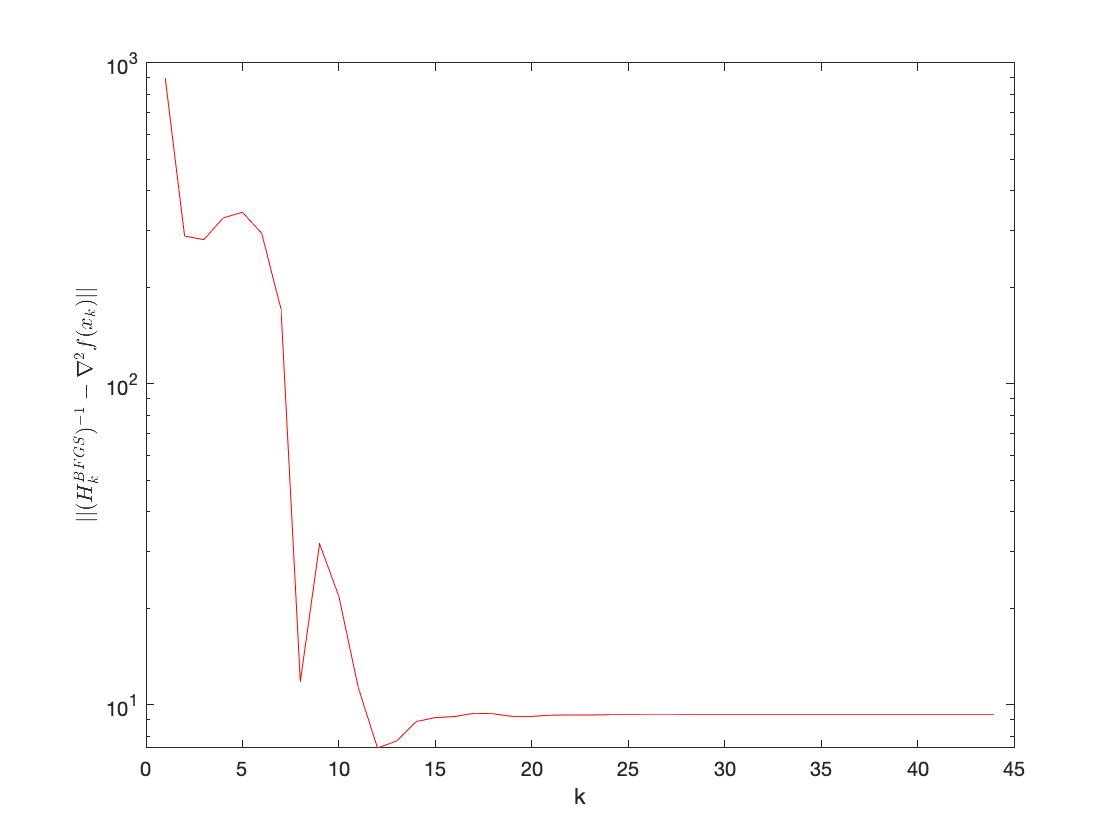

figure, plot(eii, 'r-')
set(gca, 'YScale', 'log')
xlabel('k')
ylabel('$||(H_{k}^{BFGS})^{-1} - \nabla^{2}f(x_{k})||$', 'Interpreter',"latex")
saveas(gcf, 'Artworks/3eii-bfgs-log.png')

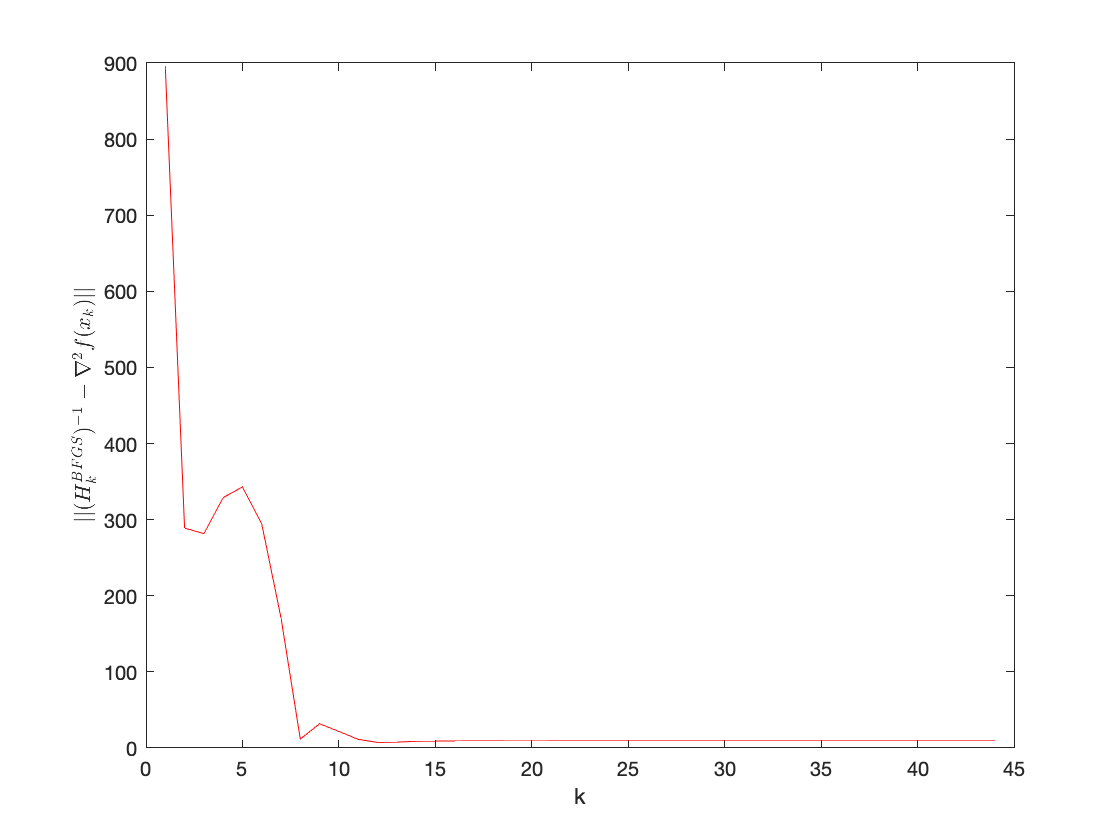


figure, plot(eii, 'r-')
xlabel('k')
ylabel('$||(H_{k}^{BFGS})^{-1} - \nabla^{2}f(x_{k})||$', 'Interpreter',"latex")
saveas(gcf, 'Artworks/3eii-bfgs.png')